# **BIO434: Intro to to Preprocessing and EEG Data Analysis**

%% BIO434: Human Electrophysiology
% Data preprocessing and analyses in frequency space part 2
% Teacher: Vanessa Kasties, vanessa.kasties@kispi.uzh.ch
% v1.0, 14.12.2023

% a clean workspace for a fresh mind
clear
close all
clc

% path to data
mydata = 'E:/COURSE_DATA/Example_Data/' %replace by your path

mydata = 'E:/COURSE_DATA/Example_Data/'


%EEGlab
addpath ('C:/Users/vakas/GitHub/eeglab/') %replace by your path
eeglab

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\vakas\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "bva-io" v1.72 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.3 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.7.1 (see >> help eegplugin_firfilt)
You are using the latest version of EEGLAB.


close

%functions
addpath(genpath('C:/Users/vakas/GitHub/BIO434/easy_topography/')); %replace by your path
addpath('C:/Users/vakas/GitHub/BIO434/functions/'); %replace by your path

## **Complex Sine Waves**

Complex sine waves are the "templates" used in FFT, that the real signal will be compared against. You already know one variant of the formula for complex sine waves. According to **Euler's Formula**, it can be rewritten like that:


$$m\left(\cos \left(k\right)+i*\sin \left(k\right)\right)={\textrm{me}}^{\textrm{ik}}$$


where $k=2\pi \textrm{ft}+\theta$, the argument of a sine wave, and m is the amplitude.

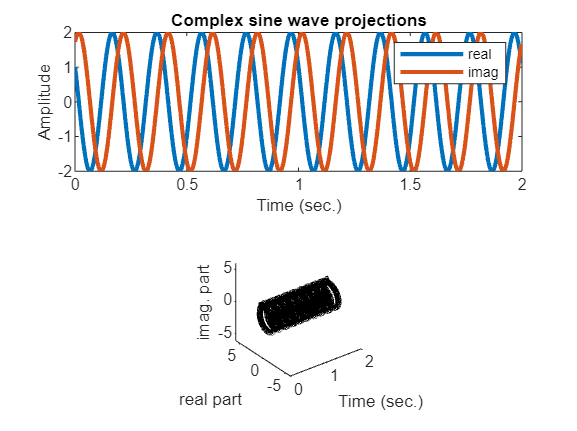

% general simulation parameters
srate = 500; % sampling rate in Hz
time  = 0:1/srate:2-1/srate; % time in seconds

% sine wave parameters
freq = 5;    % frequency in Hz
ampl = 2;    % amplitude in a.u.
phas = pi/3; % phase in radians

% generate the complex sine wave
csw = ampl*exp( 1i* ( ) );


% plot in 2D
figure
subplot(211)
plot(time,real(csw), time,imag(csw),'linew',2)
xlabel('Time (sec.)'), ylabel('Amplitude')
title('Complex sine wave projections')
legend({'real';'imag'})

% plot in 3D
subplot(212)
plot3(time,real(csw),imag(csw),'k','linew',3)
xlabel('Time (sec.)'), ylabel('real part'), zlabel('imag. part')
set(gca,'ylim',[-1 1]*ampl*3,'zlim',[-1 1]*ampl*3)
axis square
rotate3d on

## **Manual Fourier Transform**

%% generate signal
% Define the time vector
tp = 0:1/srate:10; % Time vector from 0 to 10 seconds with a sampling interval of 0.002 seconds (sampling rate of 500 Hz)

% Define frequencies of sine waves
frequencies = [0.1, 1, 12, 25, 30]; % Frequencies in Hz
amplitudes = [3, 2, 1, 2, 0.5];
% Generate the mixture of sine waves
signal = zeros(size(tp)); % Initialize the signal vector

for i = 1:length(frequencies)
    % Add the sine wave to the signal
    signal = signal + amplitudes(i) * sin(2 * pi * frequencies(i) * tp);
end

%% The Fourier transform in a loop
% prepare some parameters
N           = length(signal); % length of sequence
fourierTime = (0:N-1)/N;      % "time" used for sine waves
nyquist     = ;        % Nyquist frequency -- the highest frequency you can measure in the data

% The frequency resolution is 0.1 Hz - this is the lowest frequency you can
% fit in the current epoch length (10s). The number of frequencies that
% will be returned by the Fourier transform happens to be 1/2 of the number
% of data points (Nyquist theorem!) in the time series (plus DC offset  = frequency 0)
freqres = 1/tp(end);
freqs = 0:freqres:nyquist;
disp(['Length of frequency vector: ', num2str(length(freqs))]);

Length of frequency vector: 2501


disp(['Length of signal in samples: ', num2str(N)]);

Length of signal in samples: 5001


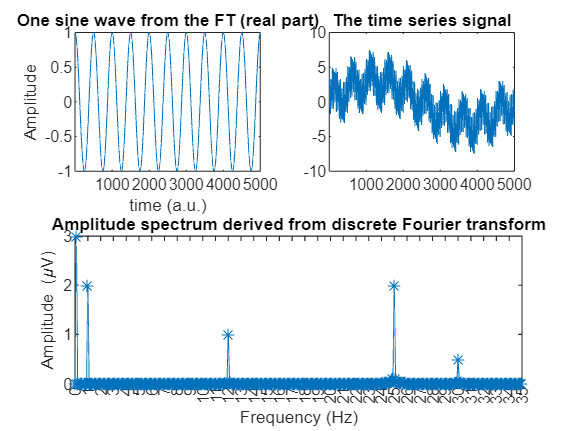


% initialize Fourier output matrix
fourierCoefs = zeros(size(freqs));

% loop over frequencies
for fi=1:length(freqs)

    % create sine wave for this frequency
    fourierSine = exp( -1i*2*pi*(fi-1).*fourierTime ); % complex sine wave with amplifude 1

    % compute dot product
    fourierCoefs(fi) = sum( fourierSine.*signal ); %dot product of complex sine of frequency f with signal

end

% scale Fourier coefficients to original scale
fourierCoefs = fourierCoefs / N;


figure(1), clf
subplot(221)
plot(real(exp( -2*pi*1i*(10).*fourierTime )))
xlabel('time (a.u.)'), ylabel('Amplitude')
set(gca,'xlim',[1 N])
title('One sine wave from the FT (real part)')

subplot(222)
plot(signal)
title('The time series signal')
set(gca,'xlim',[1 N])

subplot(212)
ampl = fourierCoefs(1:length(freqs)); % something needs to be added here!
plot(freqs,ampl,'*-')
xlabel('Frequency (Hz)')
ylabel('Amplitude (\muV)')
title('Amplitude spectrum derived from discrete Fourier transform')
set(gca,'xlim',[0 max(frequencies)+5],'xtick',0:35)

## **Fast Fourier Transform**

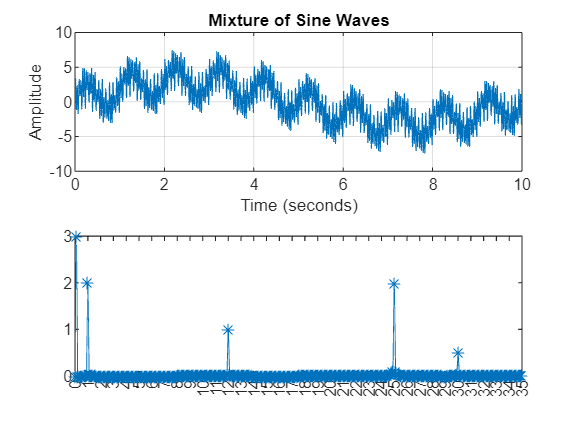

% Plot the mixture of sine waves
figure;
subplot(211)
plot(tp, signal);
title('Mixture of Sine Waves');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

subplot(212)
f  = fft(signal)/N; %calcualte Fourier coefficients with fft function
hz = linspace(0,nyquist,floor(N/2)+1);
plot(hz,abs(f(1:length(hz)))*2, '*-') %calculate power
set(gca,'xlim',[0 35],'xtick',0:35,'ylim',[0 3])

## Work on Data: Frequency Spectra

Import rereferenced data

% load data
cd(mydata)
mastoid_files = dir('B_Rereferenced_Mastoids_*.mat')

mastoid_files = struct with fields:
       name: 'B_Rereferenced_Mastoids_BIO320_001_20221207_102804.newEGI01filt_muV_int.mat'
     folder: 'E:\COURSE_DATA\Example_Data'
       date: '19-Dez-2023 00:03:38'
      bytes: 688916281
      isdir: 0
    datenum: 7.3924e+05


average_files = dir('B_Rereferenced_Average_*.mat')

average_files = struct with fields:
       name: 'B_Rereferenced_Average_BIO320_001_20221207_102804.newEGI01filt_muV_int.mat'
     folder: 'E:\COURSE_DATA\Example_Data'
       date: '19-Dez-2023 00:04:10'
      bytes: 692561328
      isdir: 0
    datenum: 7.3924e+05


load(fullfile(mastoid_files.folder, mastoid_files.name));
load(fullfile(average_files.folder, average_files.name));

disp(EEG90_M1M2)

             setname: ' resampled'
            filename: ''
            filepath: ''
             subject: ''
               group: ''
           condition: ''
             session: []
            comments: ''
              nbchan: 128
              trials: 1
                pnts: 691200
               srate: 128
                xmin: 0
                xmax: 5.4000e+03
               times: [0 7.8125 15.6250 23.4375 31.2500 39.0625 46.8750 54.6875 62.5000 70.3125 78.1250 85.9375 93.7500 101.5625 109.3750 117.1875 125 132.8125 140.6250 148.4375 156.2500 164.0625 171.8750 179.6875 187.5000 195.3125 … ] (1×691200 double)
            timesSec: [0 0.0010 0.0020 0.0030 0.0040 0.0050 0.0060 0.0070 0.0080 0.0090 0.0100 0.0110 0.0120 0.0130 0.0140 0.0150 0.0160 0.0170 0.0180 0.0190 0.0200 0.0210 0.0220 0.0230 0.0240 0.0250 0.0260 0.0270 0.0280 0.0290 … ] (1×5400000 single)
                data: [128×691200 double]
              icaact: []
             icawinv: []
           icasphere: []
      

disp(EEG90_AVG)

             setname: ' resampled'
            filename: ''
            filepath: ''
             subject: ''
               group: ''
           condition: ''
             session: []
            comments: ''
              nbchan: 128
              trials: 1
                pnts: 691200
               srate: 128
                xmin: 0
                xmax: 5.4000e+03
               times: [0 7.8125 15.6250 23.4375 31.2500 39.0625 46.8750 54.6875 62.5000 70.3125 78.1250 85.9375 93.7500 101.5625 109.3750 117.1875 125 132.8125 140.6250 148.4375 156.2500 164.0625 171.8750 179.6875 187.5000 195.3125 … ] (1×691200 double)
            timesSec: [0 0.0010 0.0020 0.0030 0.0040 0.0050 0.0060 0.0070 0.0080 0.0090 0.0100 0.0110 0.0120 0.0130 0.0140 0.0150 0.0160 0.0170 0.0180 0.0190 0.0200 0.0210 0.0220 0.0230 0.0240 0.0250 0.0260 0.0270 0.0280 0.0290 … ] (1×5400000 single)
                data: [128×691200 double]
              icaact: []
             icawinv: []
           icasphere: []
      

Generate spectral plot (for this you will have to get the [EEGLab](https://github.com/sccn/eeglab) repository)

chan = [11, 36, 104, 62]; %Fz, C3, C4, Pz
%try to plot the signal for different channels!
roi_data = EEG90_M1M2.data(chan,:); 
fs = EEG90_M1M2.srate;

figure
[spectra,freqs,~, ~,~] = spectopo(roi_data, 0, fs, 'freqrange', [0 30])

Computing spectra (window length 128; fft length: 128; overlap 0):
....
Click on each trace for channel/component index


spectra =    24.9298   30.3940   26.8459   20.8187   17.4521   15.8638   15.4392   14.9106   14.3077   13.1357   10.1335    8.1748    6.2633    4.9664    3.9514    3.0768    2.1921    1.2490    0.0761   -0.7186   -0.8528   -1.0268   -1.7043   -2.1526   -2.2411   -2.5228   -2.6200   -2.9273   -3.3764   -3.6073   -3.9697   -3.9473   -4.2702   -4.6838   -4.3482   -5.3602   -6.2049   -6.4708   -7.5718   -8.9866  -10.0594  -12.1422  -13.7649  -16.0535  -18.5988  -21.5519  -23.4950  -24.8587  -25.4776  -25.7524
   22.0670   27.0245   23.4659   18.3531   15.4026   13.6035   13.1122   12.7624   11.6027    9.9398    7.4924    5.9985    4.2904    3.4750    4.4529    4.3278    2.4493    1.1704    0.2841   -0.2192   -0.3795   -0.2619   -0.6491   -0.8822   -1.6748   -1.5558   -1.3039   -1.2650   -1.7919   -2.6588   -2.7679   -3.1447   -2.7817   -2.9637   -3.3072   -4.1193   -4.7109   -5.5171   -6.3058   -7.3016   -8.6228  -11.4648  -12.2942  -15.1037  -17.2630  -21.1259  -24.3677  -26.4333  -27.952

freqs =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


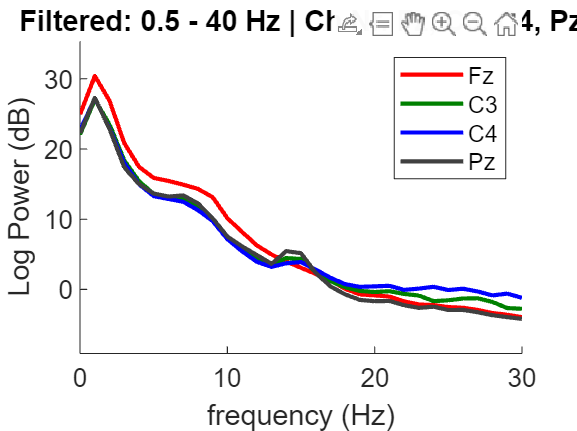

hold on
legend({'Fz', 'C3', 'C4', 'Pz'}, 'Location','northeast');
xlabel('frequency (Hz)');
ylabel('Log Power (dB)')
title(sprintf('Filtered: 0.5 - 40 Hz | Ch Nr. Fz, C3, C4, Pz'), 'Interpreter', 'none')
hold off

## Work on Data: Short-Time FFT applied to Sleep Data

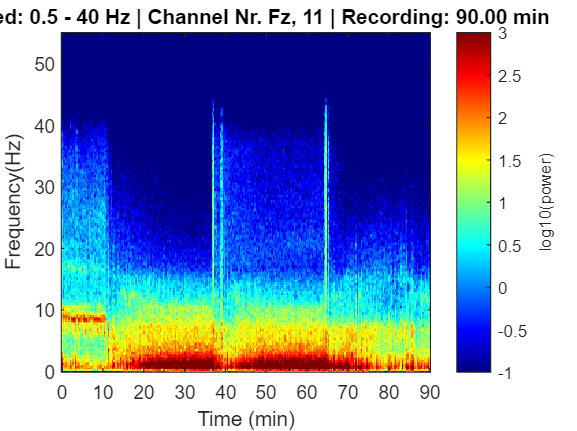

%% Spectrogram (Frequency-Time Plot) for one filtered EEG channel
chan = 11;
%try to plot the signal for different channels!
roi_data = EEG90_M1M2.data(chan,:)'; 
npnts   = EEG90_M1M2.pnts;
nmins  = npnts/fs/60; %recording length in minutes

figure
[ffttot, frange] = pWelchByEpoch(roi_data, fs, 20, 4, [], 221);
nepo = floor(length(roi_data)/fs/20);
xtime = linspace(0, nmins, nepo);
imagesc(xtime, frange, squeeze(log10(ffttot)))
set(gca,'ydir','normal')
cb=colorbar;
xlabel(cb,'log10(power)')
colormap('jet')
caxis([-1 3])
ylabel('Frequency(Hz)')
xticks([])
title(sprintf('Filtered: 0.5 - 40 Hz | Channel Nr. Fz, %d | Recording: %.2f min', chan, nmins), 'Interpreter', 'none')
xticks(0:10:90);
xlabel('Time (min)')

## **Work on Data: Topography of Slow Waves and Spindles with different References**

%% For M1M2 referenced data
% Run FFT on all channels over time
[ffttot, frange] = pWelchByEpoch(EEG90_M1M2.data(:,:)', fs, 20, 4, [], 221);

disp(size(ffttot)); %check output

   128   221   270



disp(frange);

         0
    0.2500
    0.5000
    0.7500
    1.0000
    1.2500
    1.5000
    1.7500
    2.0000
    2.2500
    2.5000
    2.7500
    3.0000
    3.2500
    3.5000
    3.7500
    4.0000
    4.2500
    4.5000
    4.7500
    5.0000
    5.2500
    5.5000
    5.7500
    6.0000
    6.2500
    6.5000
    6.7500
    7.0000
    7.2500
    7.5000
    7.7500
    8.0000
    8.2500
    8.5000
    8.7500
    9.0000
    9.2500
    9.5000
    9.7500
   10.0000
   10.2500
   10.5000
   10.7500
   11.0000
   11.2500
   11.5000
   11.7500
   12.0000
   12.2500
   12.5000
   12.7500
   13.0000
   13.2500
   13.5000
   13.7500
   14.0000
   14.2500
   14.5000
   14.7500
   15.0000
   15.2500
   15.5000
   15.7500
   16.0000
   16.2500
   16.5000
   16.7500
   17.0000
   17.2500
   17.5000
   17.7500
   18.0000
   18.2500
   18.5000
   18.7500
   19.0000
   19.2500
   19.5000
   19.7500
   20.0000
   20.2500
   20.5000
   20.7500
   21.0000
   21.2500
   21.5000
   21.7500
   22.0000
   22.2500
   22.5000

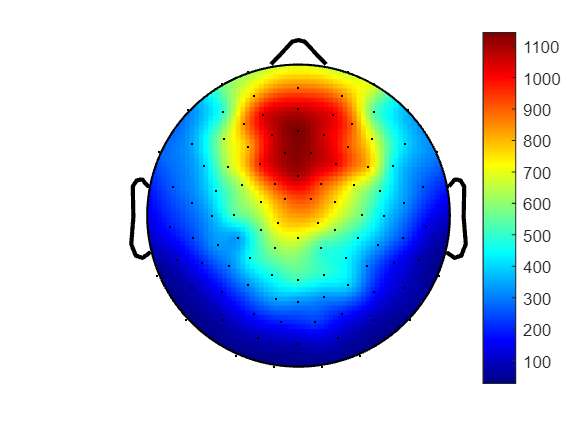


%% Slow-wave activity
% Select a frequency range and average
swa = mean(ffttot(:,3:17,:),2,'omitnan'); %slow-wave range from 0.5 to 4 Hz
swa = squeeze(swa);

%% Spindles
sigma = mean(ffttot(:,45:65,:),2,'omitnan'); %spindle range from 11 to 16 Hz
sigma = squeeze(sigma);

% Select a time window (e.g. 5 min) and average
swa_5min = mean(swa(:,90:105),2,'omitnan'); %randomly select 5 min = 15 epochs and average; we select an area with high SWA (see plot above)


% Plot topography in this time window
figure
topohelper(swa_5min, EEG90_M1M2.chanlocs) %this function uses the EEGLab repository and requires a 1D vector and the channel locations outline as an input


% Task: Also plot the topography for spindles and for the average
% referenced data!